width = 1.5 ; % Line thickness
lsize = 14 ; tsize = 14 ; legsize = 12 ; msize =8 ; % Font size in plots, label, %title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MATLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0]; grey = [0.5 0.5 0.5];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%cmap=flip(colormap(parula(5))); cmap=cmap(2:5,:);
%cmap=flip(redbluecmap(4))
cmap = [red;orange;lblue;blue]

cmap =     0.6350    0.0780    0.1840
    0.8500    0.3250    0.0980
    0.3010    0.7450    0.9330
         0    0.4470    0.7410



%diamond
Hu_et_al_fig16_diamond_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_diamond_cd=[0.003117409,0.002753036,0.002631579,0.003481781,0.006396761,0.028380567,0.089959514,0.081700405,0.075870445,0.069433198,0.051336032,0.041376518,0.035668016,0.031781377,0.028744939,0.026558704,0.024493927,0.02291498,0.02145749,0.020242915,0.019271255,0.018178138,0.017449393,0.016720648,0.015748988,0.0151417,0.014777328,0.01417004,0.013562753,0.013076923,0.012712551];

Hu_et_al_fig16_diamond_machs = Hu_et_al_fig16_diamond_machs(1,11:23)

Hu_et_al_fig16_diamond_machs =     1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000


Hu_et_al_fig16_diamond_cd = Hu_et_al_fig16_diamond_cd(1,11:23)

Hu_et_al_fig16_diamond_cd =     0.0513    0.0414    0.0357    0.0318    0.0287    0.0266    0.0245    0.0229    0.0215    0.0202    0.0193    0.0182    0.0174


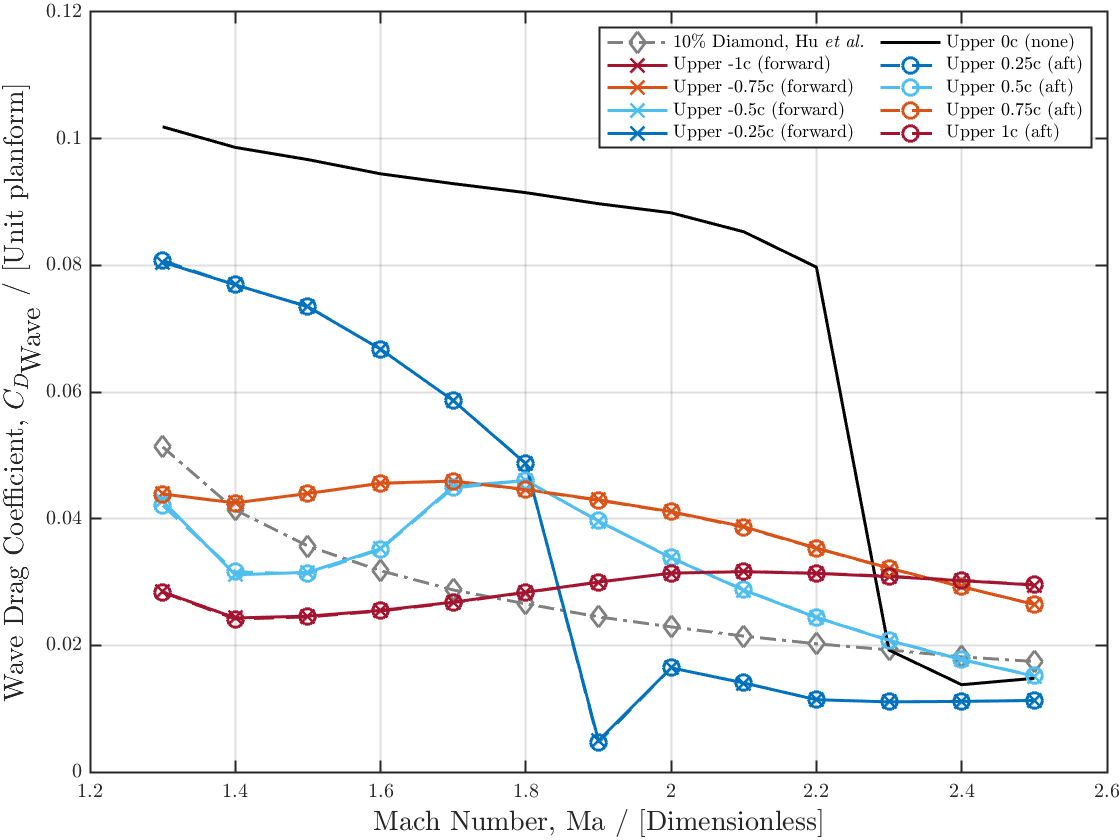


load("cd_stag_accel.mat")
Machs = [1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
figure
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'d-.',"LineWidth",width,"MarkerSize",msize,'color',grey)
plot(Machs,cd_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machs,cd_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machs,cd_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machs,cd_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machs,cd_stag_accel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)
plot(Machs,cd_stag_accel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machs,cd_stag_accel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machs,cd_stag_accel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machs,cd_stag_accel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))

grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
legend('10\% Diamond, Hu \textit{et al.}',...
    'Upper -1c (forward)','Upper -0.75c (forward)',...
    'Upper -0.5c (forward)','Upper -0.25c (forward)',...
    'Upper 0c (none)','Upper 0.25c (aft)','Upper 0.5c (aft)',...
    'Upper 0.75c (aft)','Upper 1c (aft)','NumColumns',2)
%title('\textbf{Accelerating stagger simulation Wave Drag Coefficients,} $-1c<\Delta x<1c$','FontSize',tsize)
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

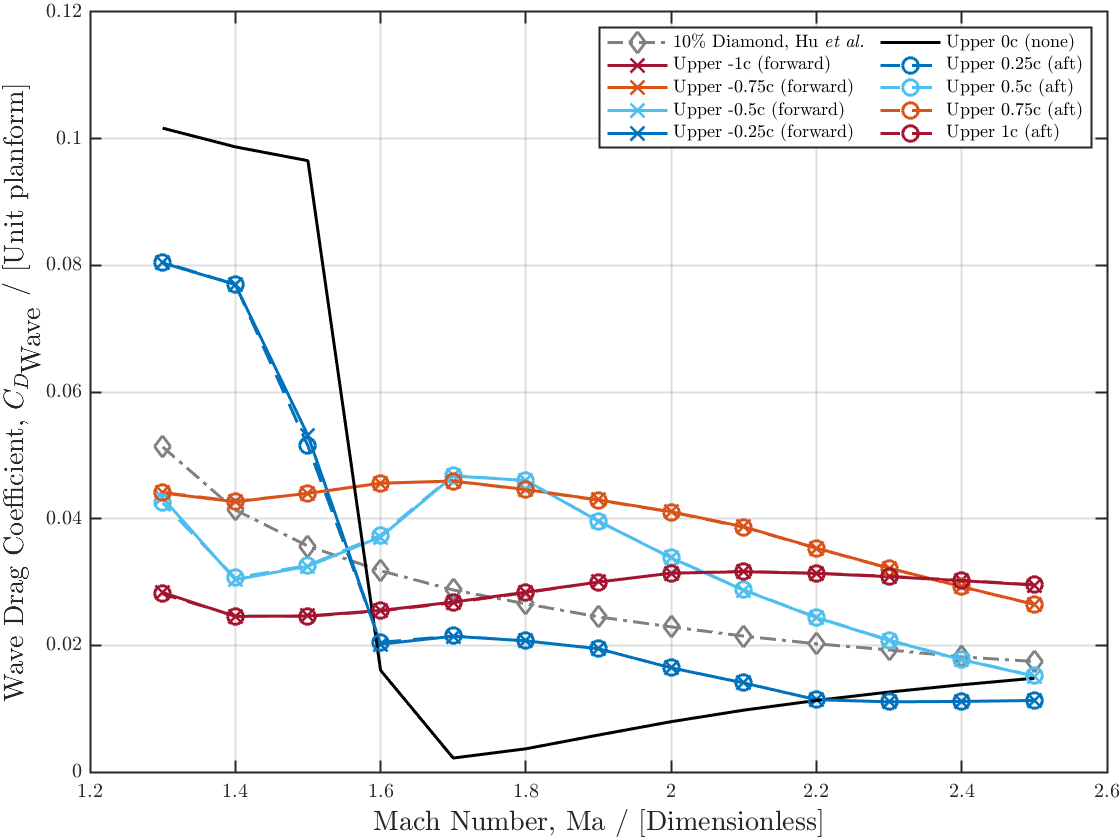


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Machsr = flip(Machs);

load("cd_stag_deccel.mat")
figure
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'d-.',"LineWidth",width,"MarkerSize",msize,'color',grey)

plot(Machsr,cd_stag_deccel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machsr,cd_stag_deccel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,cd_stag_deccel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,cd_stag_deccel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machsr,cd_stag_deccel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)
plot(Machsr,cd_stag_deccel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machsr,cd_stag_deccel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,cd_stag_deccel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,cd_stag_deccel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))

grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
legend('10\% Diamond, Hu \textit{et al.}',...
    'Upper -1c (forward)','Upper -0.75c (forward)',...
    'Upper -0.5c (forward)','Upper -0.25c (forward)',...
    'Upper 0c (none)','Upper 0.25c (aft)','Upper 0.5c (aft)',...
    'Upper 0.75c (aft)','Upper 1c (aft)','NumColumns',2)
%title('\textbf{Deccelerating stagger simulation Wave Drag Coefficients,} $-1c<\Delta x<1c$','FontSize',tsize)
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

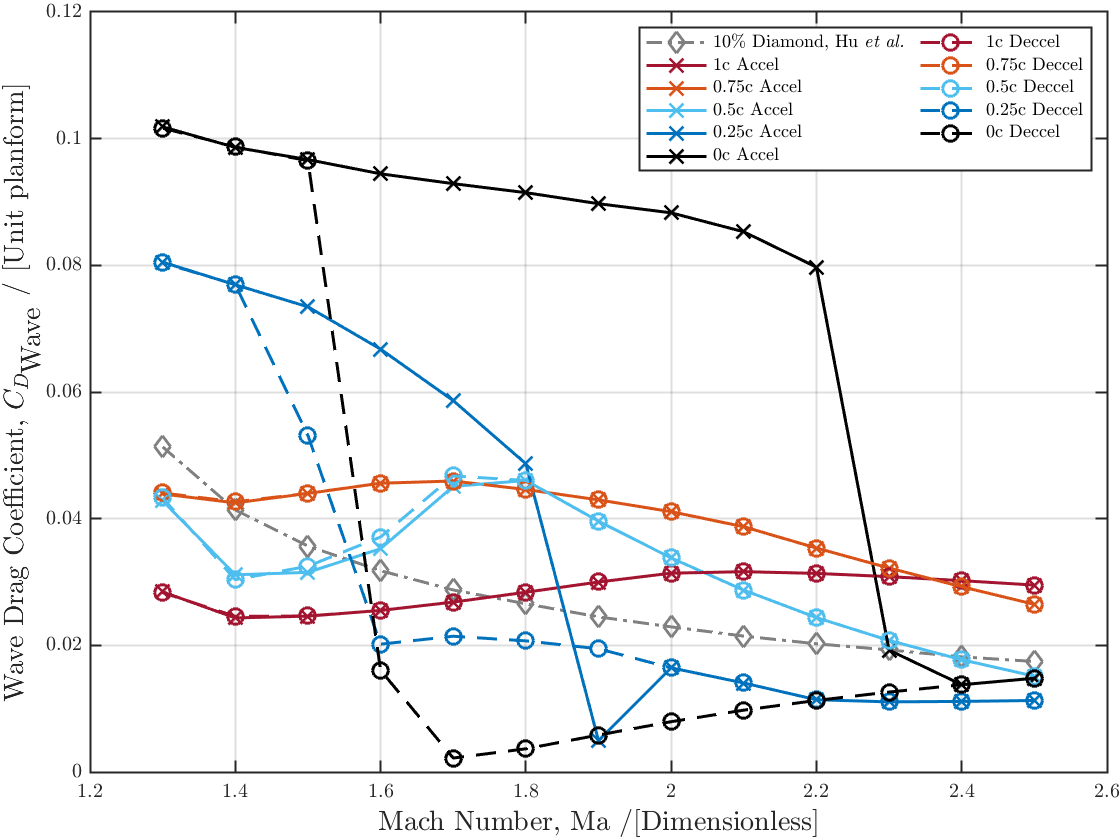


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'d-.',"LineWidth",width,"MarkerSize",msize,'color',grey)
plot(Machs,cd_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machs,cd_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machs,cd_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machs,cd_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machs,cd_stag_accel(:,5),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

plot(Machsr,cd_stag_deccel(:,1),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machsr,cd_stag_deccel(:,2),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,cd_stag_deccel(:,3),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,cd_stag_deccel(:,4),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machsr,cd_stag_deccel(:,5),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

grid on; box on; hold on
xlabel("Mach Number, $\textrm{Ma}$ /[Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
legend('10\% Diamond, Hu \textit{et al.}',...
    '1c Accel','0.75c Accel','0.5c Accel','0.25c Accel',...
    '0c Accel','1c Deccel','0.75c Deccel','0.5c Deccel',...
    '0.25c Deccel','0c Deccel','NumColumns',2)
%title('\textbf{Varying stagger simulation Wave Drag Coefficients,} $-1c<\Delta x<1c$','FontSize',tsize)
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%FIG 15 - drag coeff of acceleration process with Mach
% Diamond, busemann accel., buseman deccel, aft 0.25 accel, aft 0.25 deccel
Ma_fig_15_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_15_Machs2 = [1.2:0.1:2.5]; %simple
Ma_fig_15_Diamond   =[0.0005895691609977270,0.0005895691609977270,0.0009523809523809550,0.0022222222222222100,0.0111111111111111,0.035963718820861600,0.08693877551020410,0.08675736961451250,0.08077097505668930,0.07424036281179140,0.052471655328798200,0.0421315192743764,0.03632653061224490,0.032154195011337800,0.02925170068027210,0.026712018140589500,0.025079365079365100,0.023265306122449000,0.02163265306122450,0.020544217687074800,0.019455782312925200,0.018548752834467100,0.01764172335600910];
Ma_fig_15_Buse_acc  =[0.09818594104308390,0.09419501133786850,0.0912925170068027,0.08911564625850340,0.08730158730158730,0.08566893424036280,0.08421768707482990,0.0822222222222222,0.07895691609977320,0.07859410430839,0.010204081632653100,0.0111111111111111,0.01292517006802720,0.013650793650793600];
Ma_fig_15_Buse_decc =[0.004217687074829920,0.0056689342403628,0.010204081632653100,0.05392290249433100,0.11995464852607700,0.1368253968253970,0.12195011337868500,0.11088435374149700,0.10290249433106600,0.09818594104308390,0.09419501133786850,0.0912925170068027,0.08911564625850340,0.08730158730158730,0.002766439909297040,0.003310657596371890,0.006031746031746030,0.008027210884353740,0.009659863945578220,0.009841269841269850,0.0105668934240363,0.012743764172335600,0.013469387755102000];
Ma_fig_15_025r_acc  =[0.08367346938775510,0.08004535147392290,0.07732426303854870,0.07351473922902490,0.06734693877551020,0.058820861678004500,0.020907029478458000,0.019455782312925200,0.0165532879818594,0.015102040816326500,0.014376417233560100,0.013287981859410400,0.012199546485260800,0.011473922902494300];
Ma_fig_15_025r_decc =[0.0009523809523809550,0.0014965986394557800,0.0038548752834466900,0.02526077097505670,0.0822222222222222,0.09238095238095240,0.10507936507936500,0.0949206349206349,0.08857142857142860,0.08367346938775510,0.08004535147392290,0.07714285714285710,0.07351473922902490,0.0165532879818594,0.021269841269841200,0.020725623582766400,0.019455782312925200,0.0165532879818594,0.014013605442176900,0.011473922902494300,0.0111111111111111,0.0111111111111111,0.011473922902494300];

%FIG 17 - drag coeff of acceleration process with Mach
% Diamond, busemann accel., buseman deccel, aft 0.5 accel, aft 0.5 deccel
Ma_fig_17_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_17_05r_both  =[0.0034482758620689700,0.003632183908045960,0.0038160919540229700,0.009517241379310320,0.02533333333333330,0.04096551724137930,0.06818390804597700,0.061379310344827600,0.057701149425287400,0.05475862068965520,0.04813793103448270,0.029747126436781600,0.03195402298850570,0.036367816091954,0.046850574712643600,0.04629885057471260,0.03986206896551720,0.03360919540229880,0.028643678160919500,0.02422988505747120,0.020551724137931000,0.017609195402298800,0.015218390804597700];

%FIG 19 - drag coeff of acceleration process with Mach
% Diamond, busemann accel., buseman deccel, aft 0.75 accel, aft 0.75 deccel
Ma_fig_19_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_19_075r_both  =[0.0035944700460829300,0.0035944700460829000,0.004331797235023000,0.007096774193548340,0.017788018433179700,0.04101382488479260,0.04894009216589860,0.05317972350230410,0.05059907834101380,0.05041474654377880,0.043778801843317900,0.04248847926267280,0.04414746543778800,0.0458064516129032,0.04635944700460830,0.04525345622119810,0.04341013824884790,0.04138248847926270,0.0393548387096774,0.03603686635944700,0.03271889400921650,0.029769585253456200,0.026820276497695800];

%FIG 21 - drag coeff of acceleration process with Mach
% Diamond, busemann accel., buseman deccel, aft 1 accel, aft 1 deccel
Ma_fig_21_Machs = [0.3:0.1:2.5]; %simple
Ma_fig_21_1r_both  =[0.0031090487238978600,0.003665893271461660,0.003851508120649610,0.0051508120649652000,0.01554524361948950,0.04227378190255220,0.08348027842227380,0.07716937354988400,0.06714617169373550,0.043573085846867700,0.028352668213457000,0.024454756380510400,0.024454756380510400,0.025568445475638000,0.026867749419953600,0.02853828306264500,0.030023201856148500,0.031322505800464,0.031508120649651900,0.031322505800464,0.030951276102088100,0.030023201856148500,0.029466357308584700];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
hold on

plot(Machs,cd_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machsr,cd_stag_deccel(:,1),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Ma_fig_21_Machs,Ma_fig_21_1r_both,'^-',"LineWidth",width,'color',[0 0 0])
plot(Machs,cd_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,cd_stag_deccel(:,2),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Ma_fig_19_Machs,Ma_fig_19_075r_both,'^--',"LineWidth",width,'color',[0 0 0])
plot(Machs,cd_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,cd_stag_deccel(:,3),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Ma_fig_17_Machs,Ma_fig_17_05r_both,'^:',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])

grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
lgd = legend("OpenFOAM 1c (Accel)","OpenFOAM 1c (Deccel)",...
    "Stagger 1c Ma \textit{et al.}","OpenFOAM 0.75c (Accel)",...
    "OpenFOAM 0.75c (Deccel)","Stagger 0.75c Ma \textit{et al.}",...
    "OpenFOAM 0.5c (Accel)","OpenFOAM 0.5c (Deccel)",...
    "Stagger 0.5c Ma \textit{et al.}",...
    "Location","northeast","NumColumns",3,...
    'FontSize',legsize)

lgd =   Legend (OpenFOAM 1c (Accel), OpenFOAM 1c (Deccel), Stagger 1c Ma \textit{et al.}, OpenFOAM 0.75c (Accel), OpenFOAM 0.75c (Deccel), Stagger 0.75c Ma \textit{et al.}, OpenFOAM 0.5c (Accel), OpenFOAM 0.5c (Deccel), Stagger 0.5c Ma \textit{et al.}) with properties:

         String: {1×9 cell}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 12
       Position: [-0.0548 0.7912 0.9458 0.1148]
          Units: 'normalized'

  Show all properties


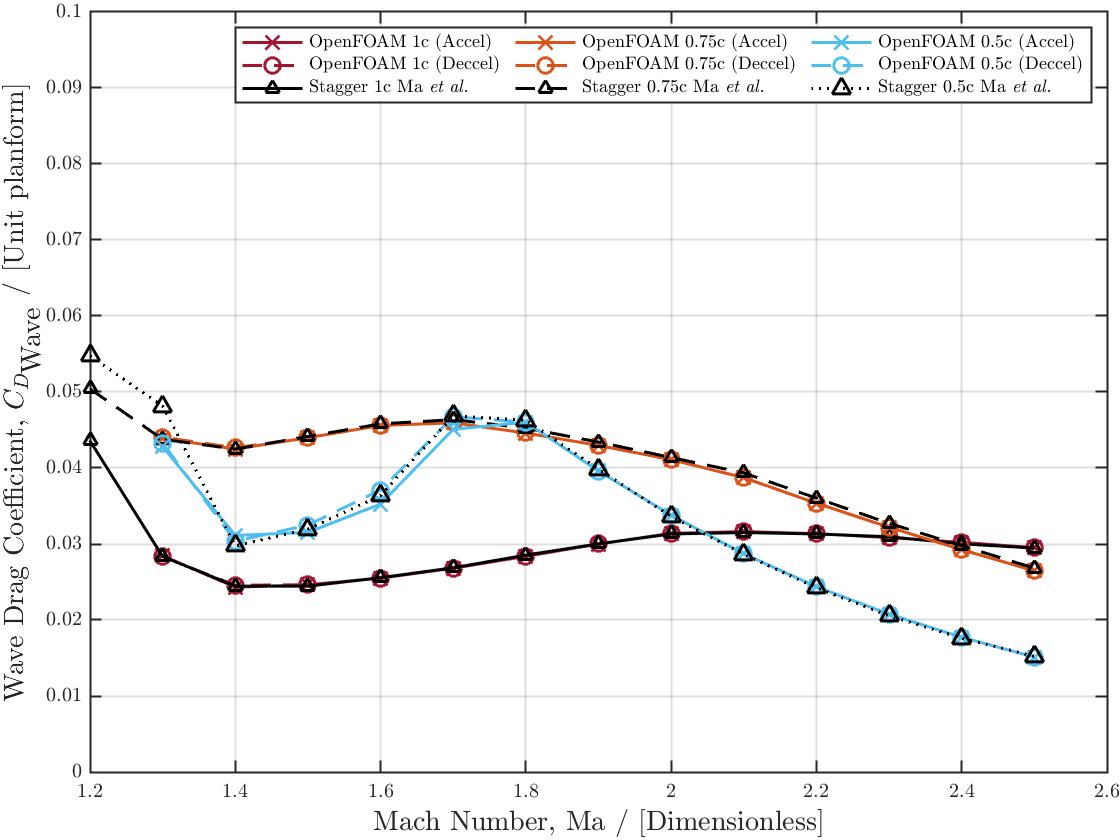

lgd.FontSize = 9;
%title('\textbf{Varying stagger simulation Wave Drag Coefficients vs Literature}','FontSize',tsize)
hold off
ylim([0 0.1])
xlim([1.2 2.6])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

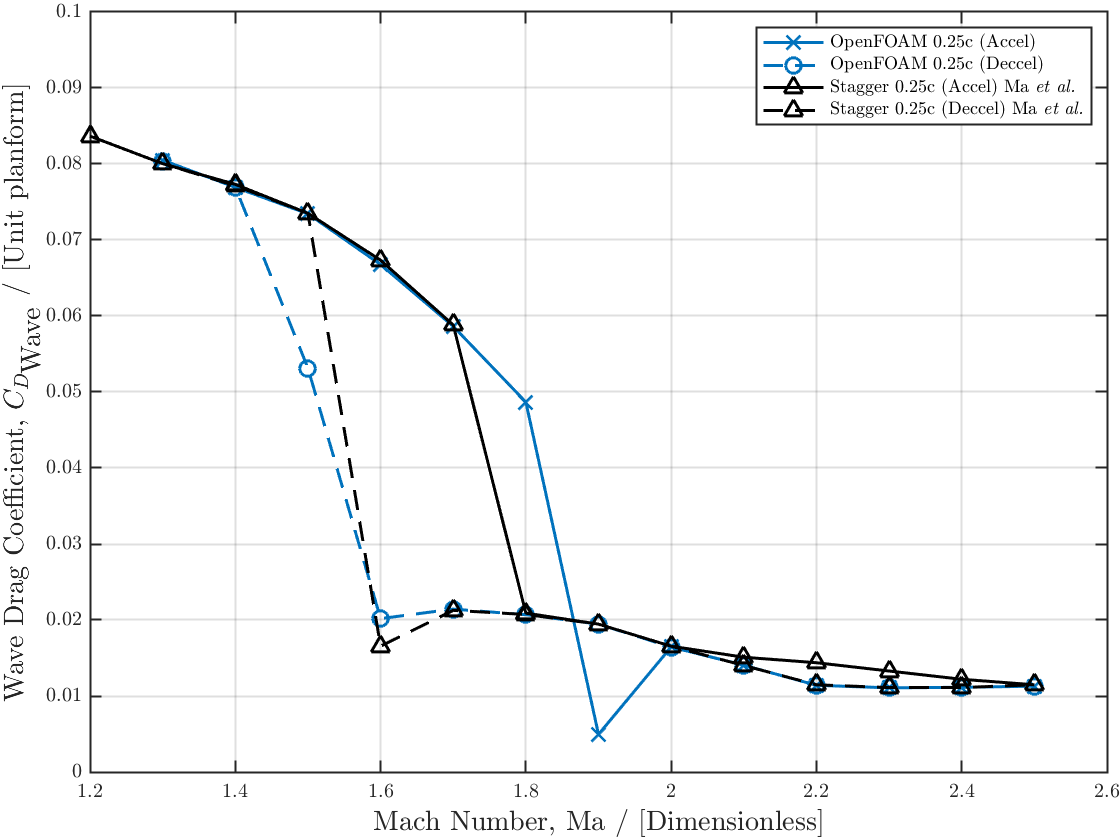


figure
hold on
plot(Machs,cd_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machsr,cd_stag_deccel(:,4),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Ma_fig_15_Machs2,Ma_fig_15_025r_acc,'^-',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])
plot(Ma_fig_15_Machs,Ma_fig_15_025r_decc,'^--',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])
grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
legend("OpenFOAM 0.25c (Accel)","OpenFOAM 0.25c (Deccel)","Stagger 0.25c (Accel) Ma \textit{et al.}","Stagger 0.25c (Deccel) Ma \textit{et al.}")
%title('\textbf{Varying stagger simulation Wave Drag Coefficients}','FontSize',tsize)
hold off
ylim([0 0.1])
xlim([1.2 2.6])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


figure
hold on
plot(Machs,cd_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machsr,cd_stag_deccel(:,1),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Ma_fig_21_Machs,Ma_fig_21_1r_both,'^-',"LineWidth",width,'color',[0 0 0])
plot(Machs,cd_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,cd_stag_deccel(:,2),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Ma_fig_19_Machs,Ma_fig_19_075r_both,'^-.',"LineWidth",width,'color',[0 0 0])
plot(Machs,cd_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,cd_stag_deccel(:,3),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Ma_fig_17_Machs,Ma_fig_17_05r_both,'^:',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])
plot(Machs,cd_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machsr,cd_stag_deccel(:,4),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Ma_fig_15_Machs2,Ma_fig_15_025r_acc,'s-',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])
plot(Ma_fig_15_Machs,Ma_fig_15_025r_decc,'^--',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])
grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
lgd = legend("OpenFOAM 1c (Accel)","OpenFOAM 1c (Deccel)",...
    "Stagger 1c Ma \textit{et al.}","OpenFOAM 0.75c (Accel)",...
    "OpenFOAM 0.75c (Deccel)","Stagger 0.75c Ma \textit{et al.}",...
    "OpenFOAM 0.5c (Accel)","OpenFOAM 0.5c (Deccel)",...
    "Stagger 0.5c Ma \textit{et al.}",...
    "OpenFOAM 0.25c (Accel)","OpenFOAM 0.25c (Deccel)",...
    "Stagger 0.25c (Accel) Ma \textit{et al.}","Stagger 0.25c (Deccel) Ma \textit{et al.}",...
    "Location","northeast","NumColumns",2,'FontSize',legsize)

lgd =   Legend (OpenFOAM 1c (Accel), OpenFOAM 1c (Deccel), Stagger 1c Ma \textit{et al.}, OpenFOAM 0.75c (Accel), OpenFOAM 0.75c (Deccel), Stagger 0.75c Ma \textit{et al.}, OpenFOAM 0.5c (Accel), OpenFOAM 0.5c (Deccel), Stagger 0.5c Ma \textit{et al.}, OpenFOAM 0.25c (Accel), OpenFOAM 0.25c (Deccel), Stagger 0.25c (Accel) Ma \textit{et al.}…) with properties:

         String: {1×13 cell}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 12
       Position: [0.1883 0.6493 0.7028 0.2567]
          Units: 'normalized'

  Show all properties


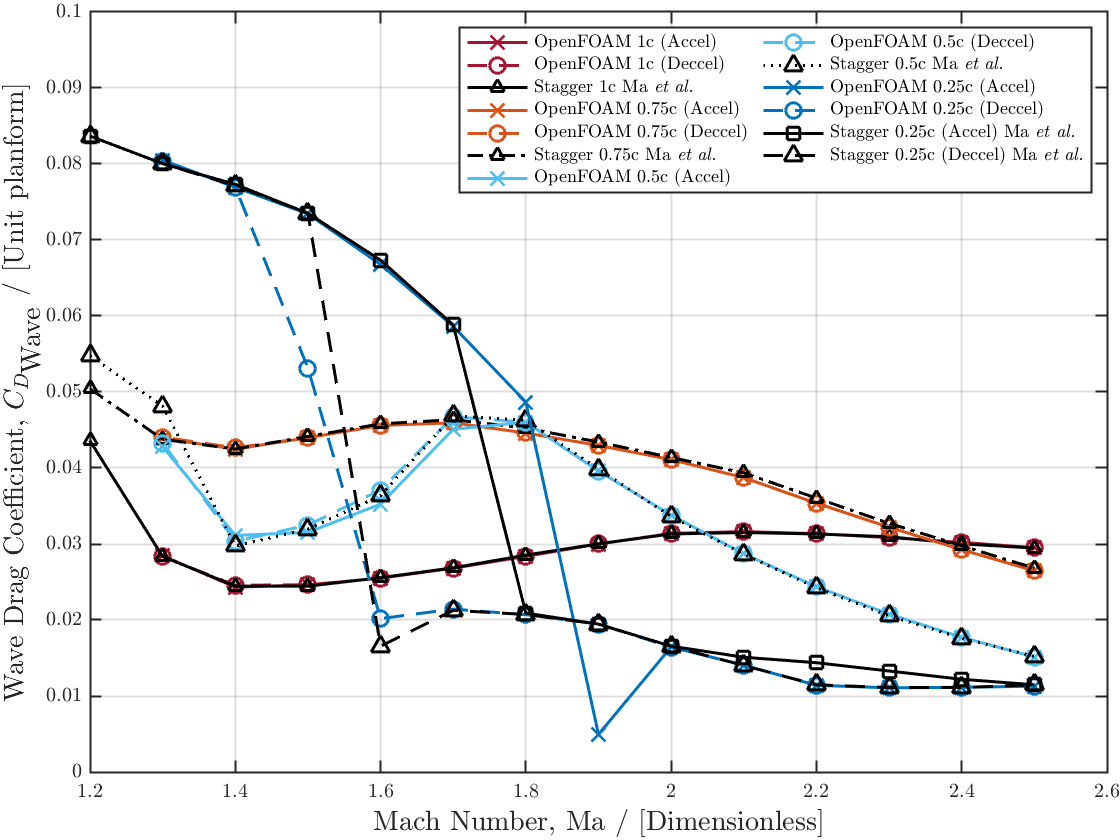

lgd.FontSize = 9;
%title('\textbf{Varying stagger simulation Wave Drag Coefficients vs Literature}','FontSize',tsize)
hold off
ylim([0 0.1])
xlim([1.2 2.6])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

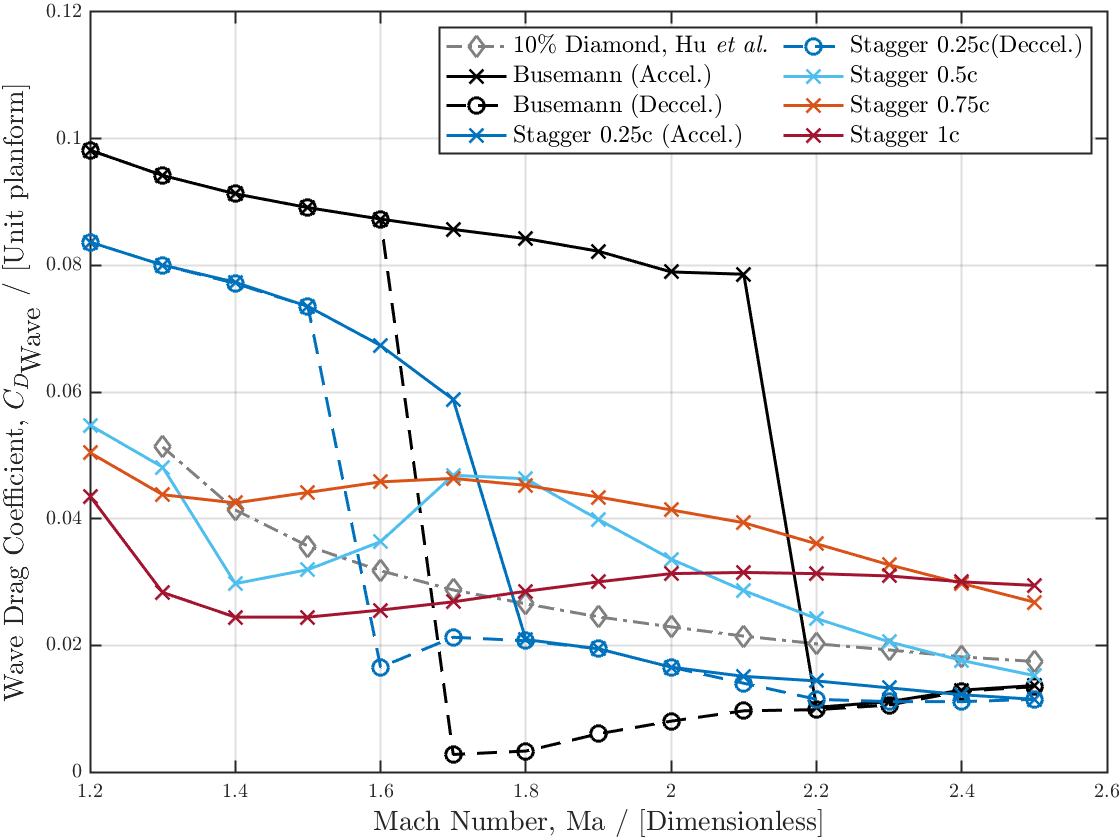


figure
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'d-.',"LineWidth",width,"MarkerSize",msize,'color',grey)
plot(Ma_fig_15_Machs2,Ma_fig_15_Buse_acc,'x-',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])
plot(Ma_fig_15_Machs,Ma_fig_15_Buse_decc,'o--',"LineWidth",width,"MarkerSize",msize,'color',[0 0 0])
plot(Ma_fig_15_Machs2,Ma_fig_15_025r_acc,'x-',"LineWidth",width,"MarkerSize",msize,'color',blue)
plot(Ma_fig_15_Machs,Ma_fig_15_025r_decc,'o--',"LineWidth",width,"MarkerSize",msize,'color',blue)
plot(Ma_fig_17_Machs,Ma_fig_17_05r_both,'x-',"LineWidth",width,"MarkerSize",msize,'color',lblue)
plot(Ma_fig_19_Machs,Ma_fig_19_075r_both,'x-',"LineWidth",width,"MarkerSize",msize,'color',orange)
plot(Ma_fig_21_Machs,Ma_fig_21_1r_both,'x-',"LineWidth",width,"MarkerSize",msize,'color',red)

xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
%title("\textbf{Literature Drag Coefficients at Zero-AoA, Ma \textit{et al.}}",'FontSize',tsize)
legend('10\% Diamond, Hu \textit{et al.}',...
    "Busemann (Accel.)","Busemann (Deccel.)",...
    "Stagger 0.25c (Accel.)","Stagger 0.25c(Deccel.)",...
    "Stagger 0.5c","Stagger 0.75c","Stagger 1c",...
    "Location","northeast","NumColumns",2,...
    'FontSize',legsize)
ylim([0 0.12])
xlim([1.2 2.6])
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

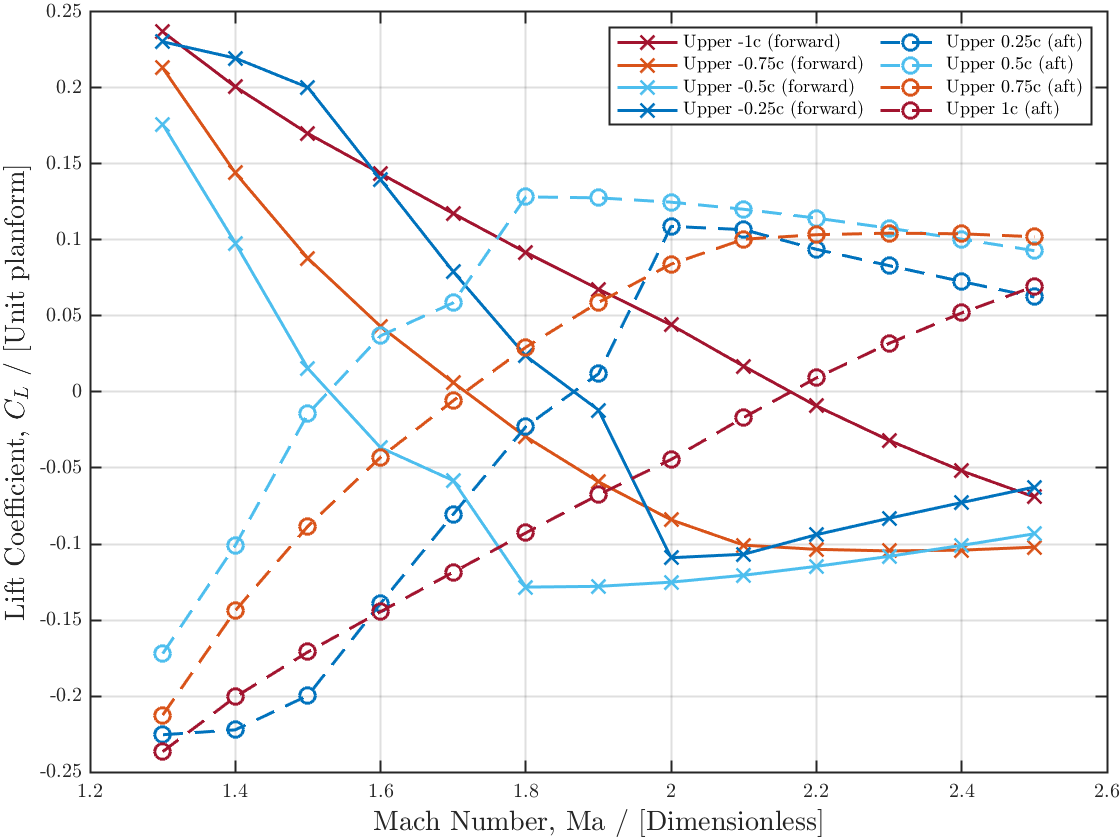


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load("cl_stag_accel.mat")
figure
hold on
plot(Machs,cl_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machs,cl_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machs,cl_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machs,cl_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))

plot(Machs,cl_stag_accel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machs,cl_stag_accel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machs,cl_stag_accel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machs,cl_stag_accel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))

grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Lift Coefficient, $C_{L}$ / [Unit planform]",'FontSize',lsize)
legend('Upper -1c (forward)','Upper -0.75c (forward)',...
    'Upper -0.5c (forward)','Upper -0.25c (forward)',...
    'Upper 0.25c (aft)','Upper 0.5c (aft)',...
    'Upper 0.75c (aft)','Upper 1c (aft)','NumColumns',2)
%title('\textbf{Accelerating stagger simulation Lift Coefficients,} $-1c<\Delta x<1c$','FontSize',tsize)
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

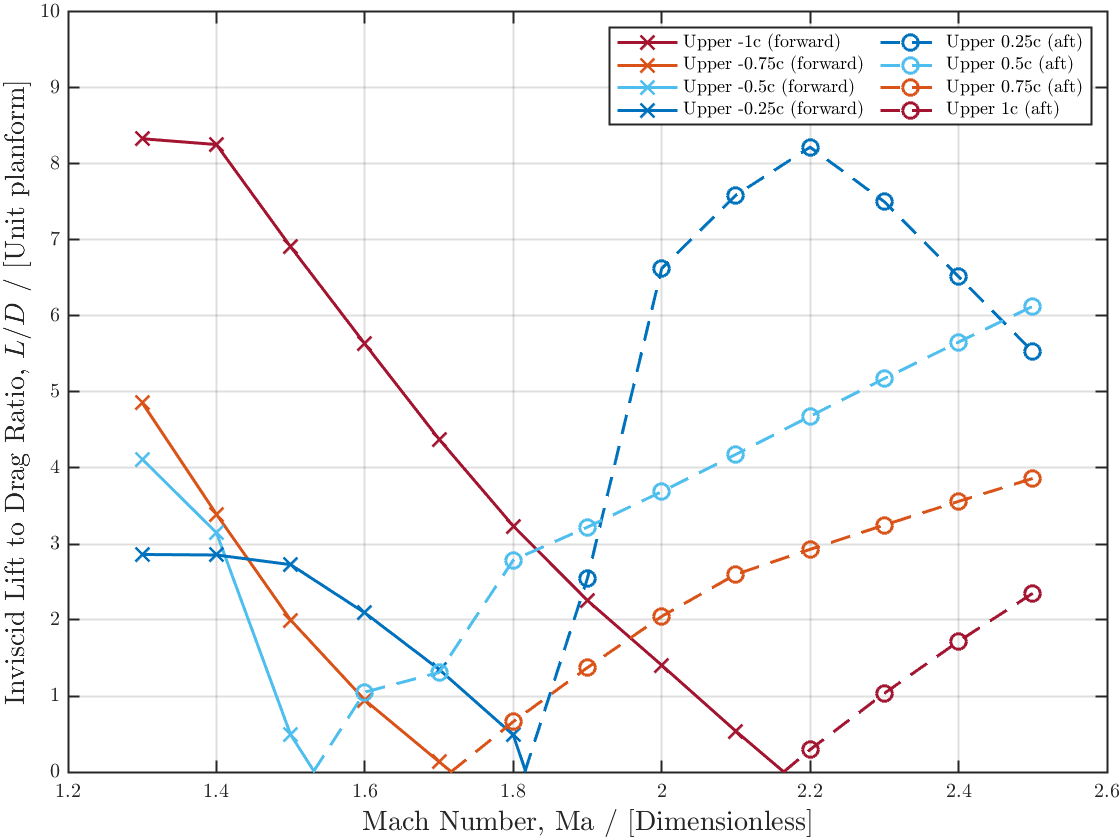


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
loverd_stag_accel = cl_stag_accel./cd_stag_accel;

figure
hold on
plot(Machs,loverd_stag_accel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machs,loverd_stag_accel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machs,loverd_stag_accel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machs,loverd_stag_accel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))

%plot(Machs,loverd_stag_accel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

plot(Machs,loverd_stag_accel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machs,loverd_stag_accel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machs,loverd_stag_accel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machs,loverd_stag_accel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))

grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Inviscid Lift to Drag Ratio, $L/D$ / [Unit planform]",'FontSize',lsize)
legend('Upper -1c (forward)','Upper -0.75c (forward)','Upper -0.5c (forward)','Upper -0.25c (forward)','Upper 0.25c (aft)','Upper 0.5c (aft)','Upper 0.75c (aft)','Upper 1c (aft)','NumColumns',2)
%title('\textbf{Accelerating stagger simulation Lift-to-Drag ratios} $L/D$,  $-1c<\Delta x<1c$','FontSize',tsize)
hold off
ylim([0 10])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

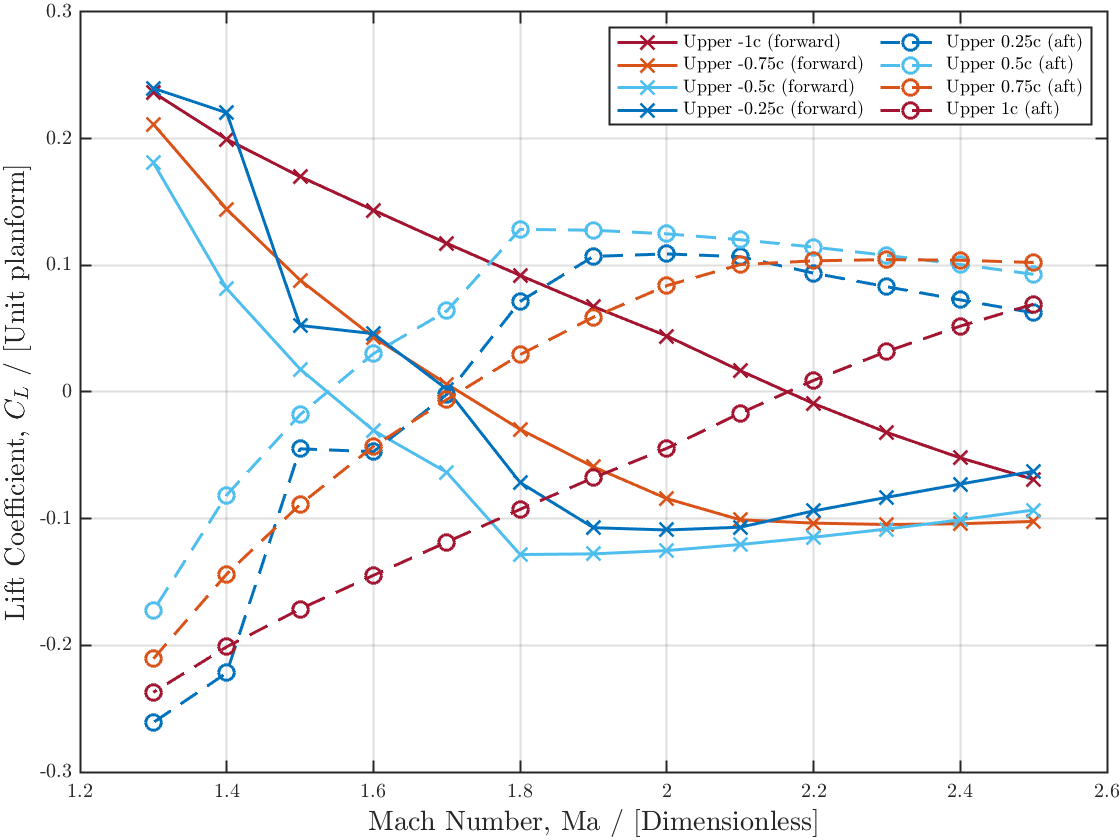


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load("cd_stag_deccel.mat")
load("cl_stag_deccel.mat")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
hold on
plot(Machsr,cl_stag_deccel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machsr,cl_stag_deccel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,cl_stag_deccel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,cl_stag_deccel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))

plot(Machsr,cl_stag_deccel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machsr,cl_stag_deccel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,cl_stag_deccel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,cl_stag_deccel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))

grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Lift Coefficient, $C_{L}$ / [Unit planform]",'FontSize',lsize)
legend('Upper -1c (forward)','Upper -0.75c (forward)','Upper -0.5c (forward)','Upper -0.25c (forward)','Upper 0.25c (aft)','Upper 0.5c (aft)','Upper 0.75c (aft)','Upper 1c (aft)','NumColumns',2)
%title('\textbf{Deccelerating stagger simulation Lift Coefficients,} $-1c<\Delta x<1c$','FontSize',tsize)
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

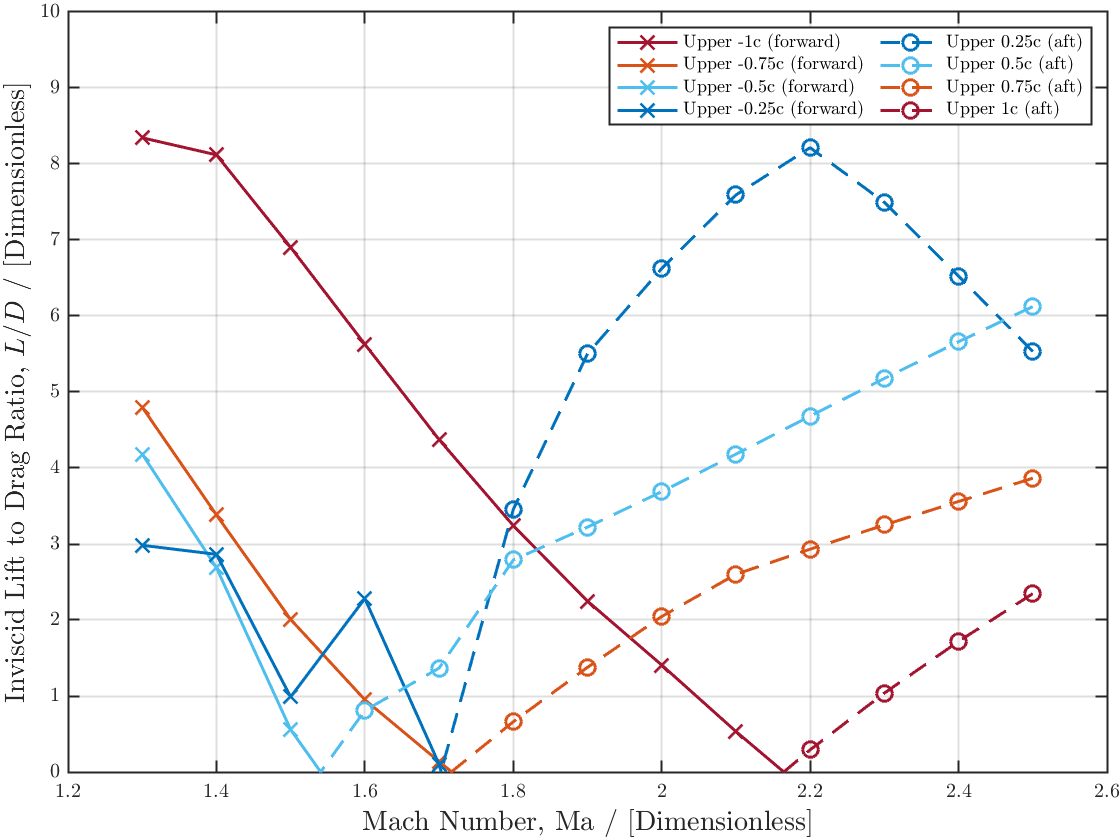


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
loverd_stag_deccel = cl_stag_deccel./cd_stag_deccel;

figure
hold on
plot(Machsr,loverd_stag_deccel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))
plot(Machsr,loverd_stag_deccel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,loverd_stag_deccel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,loverd_stag_deccel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))

%plot(Machs,loverd_stag_accel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

plot(Machsr,loverd_stag_deccel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(4,:))
plot(Machsr,loverd_stag_deccel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(3,:))
plot(Machsr,loverd_stag_deccel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(2,:))
plot(Machsr,loverd_stag_deccel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",cmap(1,:))

grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Inviscid Lift to Drag Ratio, $L/D$ / [Dimensionless]",'FontSize',lsize)
legend('Upper -1c (forward)','Upper -0.75c (forward)','Upper -0.5c (forward)','Upper -0.25c (forward)','Upper 0.25c (aft)','Upper 0.5c (aft)','Upper 0.75c (aft)','Upper 1c (aft)','NumColumns',2)
%title('\textbf{Deccelerating stagger simulation Lift-to-Drag Ratios,} $L/D$,  $-1c<\Delta x<1c$','FontSize',tsize)
hold off
ylim([0 10])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;